%1
T = import_airborne_gravity_data('Data/Q1/RESOURCES/NGS_GRAVD_Block_CN03_BETA1/NGS_GRAVD_Block_CN03_Gravity_Data_BETA1.txt');
latitude = T(:,1);
longitude = T(:,2);
elipsoidal_height = T(:,4);
gravity_filtered = T(:,3);
Ellipsoid = make_Ellipsoid('WGS84')

Ellipsoid = struct with fields:
              GM: 3.9860e+14
           omega: 7.2921e-05
    gammaEquator: 9.7803e+05
       gammaPole: 9.8322e+05
               a: 6378137
               b: 6.3568e+06
               e: 0.0818
              e2: 0.0067
               f: 0.0034


%2 
%N_ggm = open('/Users/sunilbhavsar/Documents/CE678_PROJECT/Q2/RESOURCES/AIUB-CHAMP01S_a50de3dfc2ab0cdb9a2ae28b113f3398304202075281a813ba9cc27562a667af.gdf')
%a = open('/Users/sunilbhavsar/Documents/CE678_PROJECT/AIUB-CHAMP01S_a50de3dfc2ab0cdb9a2ae28b113f3398304202075281a813ba9cc27562a667af.gdf')
nggm = import_geoid_heights('Data/Q2/Downloaded_Data/GGM02C.gdf',latitude,longitude)

nggm =   -25.4579
  -25.4563
  -25.4547
  -25.4532
  -25.4516
  -25.4501
  -25.4485
  -25.4470
  -25.4455
  -25.4440


help calc_orthometric_height

 calc_orthometric_height(ellipsoidal_height,n_ggm) - calculates orthometric height
 
     INPUT
     1. Ellipsoidal height(meters)(double)
     2. nggm(meters)(double) - Geoid height from nggm model.   
     IMP- ellipsoidal_height and n_ggm should be mapped over same latitude and longitudes
     TIP- import ellipsoidal_height and n_ggm using  import_airborne_gravity_data and import_geoid_heights  
     to ensure same latitudes and longitudes for both vectors



%adding 
orthometric_height = calc_orthometric_height(elipsoidal_height,nggm)

orthometric_height = 	1.0e+03 *

    6.3388
    6.3391
    6.3395
    6.3399
    6.3404
    6.3408
    6.3412
    6.3413
    6.3414
    6.3413


help remove_g_ggm

  remove_g_ggm(g_faa,g_ggm) calculates ong- wavelength gravity anomaly ( ∆gGGM) 
  by removing the effect of a global gravity field model from free air anomily values
  Inputs:
  g_faa   (double) - corresponding free air anomalies (mGals) 
  g_ggm   (double) - corresponding global gravity (mGals) 
  
 
  Output:
  g_msw   (double) - reduced gravity anomaly ∆gs&mw contains only the medium and the short wave- lengths.
  mapped over latitude and longitude of both g_ggm and f_faa
  IMP - Ensure that  g_faa and g_ggm are both imorted and calculated over same latitude and longitude vector
  TIP1 - Use  calc_free_air_anomaly for calculating g_faa
  TIP2 - Use  import_grav_anomaly for importing g_ggm



%3
Ellipsoid = make_Ellipsoid('WGS84');
free_air_anomily = gravity_filtered + calc_FAC(latitude,Ellipsoid,orthometric_height)-calc_gnorm_ellip_surface(latitude,Ellipsoid)

free_air_anomily = 	1.0e+03 *

   -3.8995
   -3.8996
   -3.8997
   -3.8999
   -3.9001
   -3.9003
   -3.9004
   -3.9005
   -3.9005
   -3.9005


free_air_anomily = calc_free_air_anomaly(gravity_filtered,latitude,Ellipsoid,orthometric_height)

free_air_anomily = 	1.0e+03 *

   -3.8995
   -3.8996
   -3.8997
   -3.8999
   -3.9001
   -3.9003
   -3.9004
   -3.9005
   -3.9005
   -3.9005


%4 hel

del_g_ggm = import_grav_anomaly('Data/Q4/GGM02C_Anomily.gdf',latitude,longitude)

del_g_ggm =    15.8541
   15.8520
   15.8484
   15.8451
   15.8418
   15.8385
   15.8352
   15.8316
   15.8258
   15.8204


del_g_s_and_mw = remove_g_ggm(free_air_anomily,del_g_ggm);

%5
g_atm_and_s_mw = remove_g_atm(del_g_s_and_mw,orthometric_height)

g_atm_and_s_mw = 	1.0e+03 *

   -3.9157
   -3.9158
   -3.9160
   -3.9162
   -3.9163
   -3.9165
   -3.9166
   -3.9167
   -3.9167
   -3.9168


%6
error = 0.6

error = 0.6000

[Latitude_grid,Longitude_grid] = create_grid(latitude,longitude,0.01,error);
g_atm_and_s_mw = griddata(latitude,longitude,g_atm_and_s_mw,Latitude_grid,Longitude_grid);



%7
files = ["Data/Q7/srtm_16_04/srtm_16_04.asc","Data/Q7/srtm_17_04/srtm_17_04.asc"];
H = combine_DEM_data(files,Latitude_grid,Longitude_grid)

H = 	1.0e+03 *

    0.9390    0.9120    0.9230    0.9130    0.9070    0.9120    0.9230    0.9050    0.9450    0.9230    0.9220    0.9340    0.9230    0.9420    0.9520    0.9350    0.9610    0.9290    0.9240    0.9350    0.9160    0.9350    0.9430    0.9540    0.9500    0.9430    0.9620    0.9640    0.9580    0.9780    0.9890    0.9850    0.9780    0.9690    0.9770    0.9790    0.9850    0.9950    0.9740    1.0220    0.9880    0.9840    0.9930    0.9960    0.9940    1.0000    0.9970    0.9970    1.0060    1.0110
    0.9300    0.9460    0.9030    0.9000    0.9020    0.9050    0.9030    0.9060    0.9130    0.9170    0.9140    0.9340    0.9220    0.9180    0.9150    0.9120    0.9160    0.9260    0.9380    0.9280    0.9290    0.9370    0.9480    0.9590    0.9710    0.9750    0.9780    0.9520    0.9520    0.9600    0.9610    0.9710    0.9740    0.9710    0.9880    1.0030    1.0060    1.0020    1.0120    1.0290    0.9930    0.9880    0.9950    1.0140    1.0160    1.0110    1.0020    1.0080   

tc = terrain_correction(H,Latitude_grid,Longitude_grid,0.01)

Determining spatial grids
Setting up integration kernel
FFT kernel for TC
FFT H^2
FFT H
FFT ones
Computing TC


tc =     0.0150    0.0134    0.0143    0.0103    0.0101    0.0100    0.0134    0.0142    0.0363    0.0134    0.0111    0.0144    0.0124    0.0176    0.0240    0.0143    0.0330    0.0198    0.0180    0.0136    0.0342    0.0187    0.0157    0.0152    0.0172    0.0271    0.0174    0.0163    0.0210    0.0181    0.0180    0.0153    0.0147    0.0214    0.0199    0.0200    0.0181    0.0165    0.0363    0.0377    0.0270    0.0212    0.0165    0.0155    0.0188    0.0162    0.0211    0.0254    0.0255    0.0165
    0.0144    0.0461    0.0240    0.0154    0.0131    0.0131    0.0146    0.0191    0.0128    0.0148    0.0159    0.0172    0.0158    0.0202    0.0260    0.0391    0.0277    0.0217    0.0143    0.0204    0.0213    0.0190    0.0163    0.0184    0.0263    0.0247    0.0270    0.0346    0.0414    0.0292    0.0296    0.0211    0.0211    0.0267    0.0242    0.0297    0.0273    0.0223    0.0230    0.0516    0.0267    0.0216    0.0173    0.0193    0.0165    0.0151    0.0234    0.0199    0.0205    

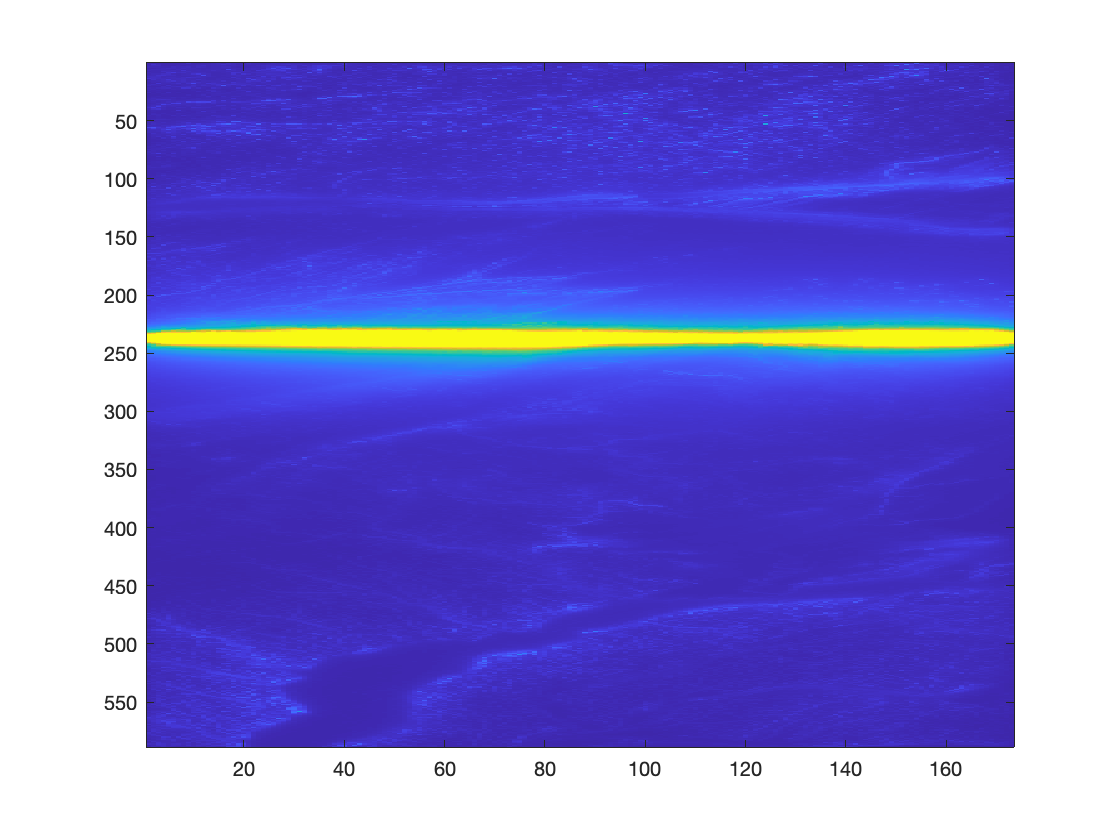

imagesc(tc)
caxis([0 1])

gfaye = g_atm_and_s_mw-tc

gfaye = 	1.0e+03 *

   -3.9211   -3.9218   -3.9224   -3.9231   -3.9238   -3.9244   -3.9641   -4.0075   -4.0509   -4.0942   -4.1375   -4.1809   -4.2242   -4.2676   -4.3110   -4.2882   -4.2487   -4.2091   -4.1695   -4.1299   -4.0903   -4.0508   -4.0112   -3.9716   -3.9611   -3.9607   -3.9602   -3.9597   -3.9592   -3.9587   -3.9582   -3.9578   -3.9573   -3.9579   -3.9591   -3.9603   -3.9614   -3.9626   -3.9638   -3.9649   -3.9661   -3.9672   -3.9672   -3.9666   -3.9660   -3.9653   -3.9647   -3.9641   -3.9635   -3.9629
   -3.9209   -3.9216   -3.9222   -3.9228   -3.9235   -3.9241   -3.9630   -4.0064   -4.0498   -4.0932   -4.1366   -4.1801   -4.2235   -4.2669   -4.3104   -4.2893   -4.2497   -4.2101   -4.1705   -4.1309   -4.0913   -4.0518   -4.0122   -3.9726   -3.9613   -3.9609   -3.9604   -3.9599   -3.9595   -3.9590   -3.9585   -3.9580   -3.9575   -3.9581   -3.9592   -3.9603   -3.9614   -3.9625   -3.9636   -3.9647   -3.9658   -3.9669   -3.9670   -3.9664   -3.9659   -3.9653   -3.9648   -3.964

%8
%and 9
Latitude_grid

Latitude_grid =    40.6908   40.7008   40.7108   40.7208   40.7308   40.7408   40.7508   40.7608   40.7708   40.7808   40.7908   40.8008   40.8108   40.8208   40.8308   40.8408   40.8508   40.8608   40.8708   40.8808   40.8908   40.9008   40.9108   40.9208   40.9308   40.9408   40.9508   40.9608   40.9708   40.9808   40.9908   41.0008   41.0108   41.0208   41.0308   41.0408   41.0508   41.0608   41.0708   41.0808   41.0908   41.1008   41.1108   41.1208   41.1308   41.1408   41.1508   41.1608   41.1708   41.1808
   40.6908   40.7008   40.7108   40.7208   40.7308   40.7408   40.7508   40.7608   40.7708   40.7808   40.7908   40.8008   40.8108   40.8208   40.8308   40.8408   40.8508   40.8608   40.8708   40.8808   40.8908   40.9008   40.9108   40.9208   40.9308   40.9408   40.9508   40.9608   40.9708   40.9808   40.9908   41.0008   41.0108   41.0208   41.0308   41.0408   41.0508   41.0608   41.0708   41.0808   41.0908   41.1008   41.1108   41.1208   41.1308   41.1408   41.1508   41.1608   

help calc_n_cogeoid

 calc_n_cogeoid(Nr,N_ggm,ggm_Latitudes,ggm_longitudes,Latitude_grid,Longitude_grid)
  calculates co-geoid height by adding initial undulation to Nggm.
  INPUT -
  1. Nr - Geoid Undulation calculated using stokes integral
  2. N_ggm - geoid heights from ggm model imported.
  3. ggm_Latitudes (double)  - Latitude(degrees) vector on which N_ggm is mapped
  4. ggm_longitudes (double) - Longitude(degrees) vector on which N_ggm is mapped
  5. Latitude_grid(double)   - Latitude(degrees) matrix used for Nr
  6. Longitude_grid(double)  - Longitude(degrees) matrix used for  Nr 
  OUTPUT - 
  gfaye(mGals) over Latitude and Longitude grid
  TIP- 
  Nr - use calc_undulation
  Nggm - use import_geoid_heights



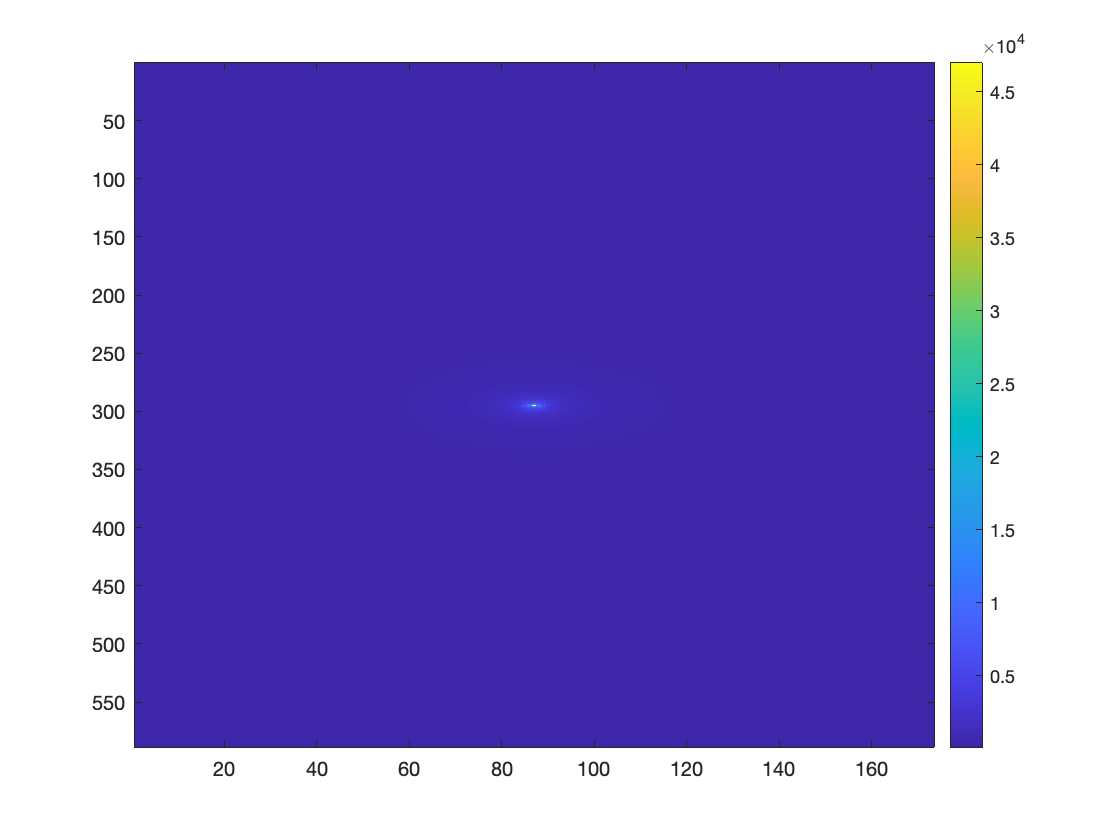

 Tr = calc_disturb_potential(Latitude_grid,Longitude_grid,gfaye)

Nr = calc_undulation(Tr,Latitude_grid,Ellipsoid);

%10
N_co_geoid = calc_n_cogeoid(Nr,nggm,latitude,longitude,Latitude_grid,Longitude_grid)

N_co_geoid =  -198.2788 -202.5607 -206.4455 -210.0855 -213.5591 -216.9311 -220.2088 -223.3985 -226.5076 -229.5397 -232.4940 -235.3650 -238.1477 -240.8312 -243.3773 -245.8175 -248.1789 -250.4752 -252.7162 -254.9100 -257.0643 -259.1870 -261.2887 -263.3919 -265.4897 -267.5720 -269.6356 -271.6793 -273.7030 -275.7066 -277.6904 -279.6549 -281.6013 -283.5305 -285.4420 -287.3357 -289.2119 -291.0709 -292.9134 -294.7395 -296.5494 -298.3428 -300.1210 -301.8849 -303.6346 -305.3709 -307.0943 -308.8052 -310.5044 -312.1927
 -201.3671 -205.8681 -209.9182 -213.6904 -217.2758 -220.7461 -224.1130 -227.3845 -230.5688 -233.6703 -236.6883 -239.6174 -242.4520 -245.1802 -247.7633 -250.2319 -252.6159 -254.9305 -257.1867 -259.3936 -261.5597 -263.6937 -265.8072 -267.9232 -270.0358 -272.1339 -274.2136 -276.2736 -278.3135 -280.3332 -282.3328 -284.3130 -286.2749 -288.2192 -290.1456 -292.0539 -293.9444 -295.8176 -297.6739 -299.5135 -301.3367 -303.1430 -304.9339 -306.7100 -308.4719 -310.2201 -311.9553 -313.6779 -315.

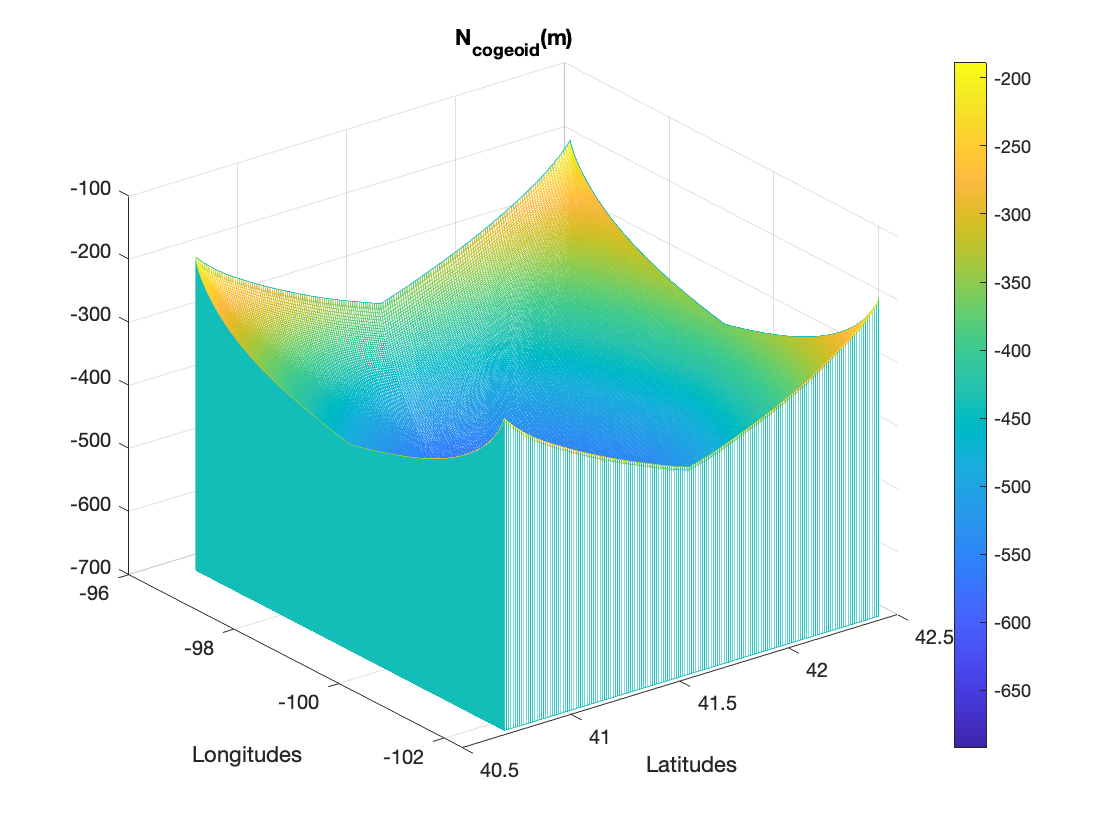

meshz(Latitude_grid,Longitude_grid,N_co_geoid)
xlabel('Latitudes')
ylabel('Longitudes')
title('N_{cogeoid}(m)')
colorbar

%11
 R = Ellipsoid.a

R = 6378137

 G = 6.67*10^-6

G = 6.6700e-06

 rho = 2670

rho = 2670

 gamma = calc_gnorm_ellip_surface(Latitude_grid,Ellipsoid);
 Xm=Longitude_grid*111319.9*cosd(mean(mean(Latitude_grid)));
 Ym=Latitude_grid*111319.9;
 
 rq = sqrt((Xm-mean(mean(Xm))).^2+(Ym-mean(mean(Ym))).^2)

rq = 	1.0e+05 *

    2.6297    2.6257    2.6217    2.6177    2.6138    2.6100    2.6061    2.6024    2.5986    2.5949    2.5913    2.5877    2.5841    2.5806    2.5771    2.5736    2.5702    2.5669    2.5636    2.5603    2.5571    2.5539    2.5508    2.5477    2.5447    2.5417    2.5387    2.5358    2.5329    2.5301    2.5274    2.5246    2.5220    2.5193    2.5167    2.5142    2.5117    2.5093    2.5069    2.5045    2.5022    2.5000    2.4978    2.4956    2.4935    2.4914    2.4894    2.4874    2.4855    2.4837
    2.6220    2.6179    2.6139    2.6100    2.6060    2.6022    2.5983    2.5945    2.5908    2.5871    2.5834    2.5798    2.5762    2.5727    2.5692    2.5657    2.5623    2.5589    2.5556    2.5523    2.5491    2.5459    2.5428    2.5397    2.5366    2.5336    2.5307    2.5278    2.5249    2.5221    2.5193    2.5165    2.5139    2.5112    2.5086    2.5061    2.5036    2.5011    2.4987    2.4964    2.4941    2.4918    2.4896    2.4874    2.4853    2.4832    2.4812    2.4792  

 rq3 =rq.^3 

rq3 = 	1.0e+16 *

    1.8186    1.8102    1.8020    1.7938    1.7858    1.7779    1.7701    1.7624    1.7548    1.7473    1.7399    1.7327    1.7255    1.7185    1.7115    1.7047    1.6979    1.6913    1.6848    1.6783    1.6720    1.6658    1.6597    1.6536    1.6477    1.6419    1.6362    1.6306    1.6251    1.6197    1.6143    1.6091    1.6040    1.5990    1.5941    1.5893    1.5846    1.5799    1.5754    1.5710    1.5667    1.5624    1.5583    1.5543    1.5503    1.5465    1.5427    1.5391    1.5355    1.5321
    1.8025    1.7942    1.7860    1.7779    1.7699    1.7620    1.7542    1.7465    1.7389    1.7315    1.7241    1.7169    1.7098    1.7027    1.6958    1.6890    1.6822    1.6756    1.6691    1.6627    1.6564    1.6502    1.6441    1.6381    1.6322    1.6264    1.6207    1.6151    1.6096    1.6042    1.5989    1.5937    1.5886    1.5836    1.5787    1.5739    1.5692    1.5646    1.5601    1.5557    1.5514    1.5472    1.5431    1.5390    1.5351    1.5313    1.5275    1.5239 

 res = 0.01;
 Delta=111319.9*res;
 % kernel weighting 
 W=(rq3./(2*Delta)).*(((rq+Delta/2).^2-(rq-Delta/2).^2)./(((rq+Delta/2).^2).*((rq-Delta/2).^2)));
 K=W./rq3;
% apply a spherical cap to zero the kernel off outside some set radius


% Free up some memory

%% compute 2D fft for the Heights, Heights^2 and kernel

 disp('FFT kernel for TC')

FFT kernel for TC


 rq(rq<111391.1*0.01) = 0;
 FK=fft2(fftshift(K));
 deltaN_indirect_term1 = pi*H.^2

deltaN_indirect_term1 = 	1.0e+06 *

    2.7700    2.6130    2.6764    2.6187    2.5844    2.6130    2.6764    2.5730    2.8055    2.6764    2.6706    2.7406    2.6764    2.7877    2.8472    2.7465    2.9013    2.7113    2.6822    2.7465    2.6360    2.7465    2.7937    2.8592    2.8353    2.7937    2.9074    2.9195    2.8832    3.0049    3.0729    3.0481    3.0049    2.9498    2.9987    3.0110    3.0481    3.1103    2.9804    3.2813    3.0666    3.0419    3.0978    3.1165    3.1040    3.1416    3.1228    3.1228    3.1794    3.2111
    2.7172    2.8115    2.5617    2.5447    2.5560    2.5730    2.5617    2.5787    2.6187    2.6417    2.6245    2.7406    2.6706    2.6475    2.6302    2.6130    2.6360    2.6938    2.7641    2.7055    2.7113    2.7582    2.8234    2.8893    2.9620    2.9865    3.0049    2.8472    2.8472    2.8953    2.9013    2.9620    2.9804    2.9620    3.0666    3.1605    3.1794    3.1542    3.2174    3.3264    3.0978    3.0666    3.1103    3.2302    3.2429    3.2111   


 deltaN_indirect_term2 = ifft2(fft2(H.^3).*FK)

deltaN_indirect_term2 =    15.3364   14.7021   14.3698   14.2849   14.2121   14.3414   14.3408   15.0406   14.7859   14.6021   14.6919   14.8624   15.0911   15.5382   15.5372   15.7572   15.1640   15.2484   15.5599   15.3844   15.6506   15.7444   16.0242   16.1155   16.2191   16.8674   17.0584   17.0180   17.7175   17.8721   17.3578   17.3870   17.2184   17.3722   17.5803   17.8514   18.1382   18.0636   18.7852   18.4474   18.2498   18.5024   18.7953   18.9584   18.9621   19.1459   19.5760   19.7218   19.7692   20.4407
   15.8107   14.9343   14.6282   14.5566   14.9736   14.6506   14.6383   14.7927   15.0735   15.4509   15.3752   15.4659   15.3929   15.4703   15.4338   15.5783   15.8971   16.1081   15.9669   16.1587   16.2492   16.7600   16.8441   17.0837   17.2701   17.3655   17.2489   18.0068   17.7659   18.0977   18.2974   18.5465   18.7358   19.2677   19.4921   19.7479   19.5621   19.8752   20.3837   19.4162   19.2025   19.5073   19.9799   20.5928   20.2950   20.3952   20.5691   20

 deltaN_indirect_term3 = - H.^3.*ifft2(fft2(1).*FK)

deltaN_indirect_term3 =    -0.4368   -0.0632   -0.0203   -0.0084   -0.0043   -0.0025   -0.0017   -0.0010   -0.0008   -0.0006   -0.0004   -0.0003   -0.0003   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.1174   -0.0427   -0.0148   -0.0070   -0.0038   -0.0023   -0.0015   -0.0010   -0.0007   -0.0005   -0.0004   -0.0003   -0.0003   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0

 rq5 = rq.^5;
 rq5(rq5<(111391.1*0.01).^5)=0;
 W=(rq5./(2*Delta)).*(((rq+Delta/2).^2-(rq-Delta/2).^2)./(((rq+Delta/2).^2).*((rq-Delta/2).^2)));
 K = W./(rq5);
 
 FK5 = fft2(fftshift(K))
 deltaN_indirect_term4 =  + 3*R^2/40 .*conv2(H.^5,rq.^5,'same')

deltaN_indirect_term4 = 	1.0e+58 *

    0.3151    0.3198    0.3245    0.3293    0.3343    0.3392    0.3442    0.3492    0.3543    0.3595    0.3646    0.3697    0.3750    0.3803    0.3856    0.3910    0.3964    0.4019    0.4073    0.4128    0.4183    0.4239    0.4296    0.4354    0.4412    0.4471    0.4531    0.4591    0.4651    0.4712    0.4773    0.4834    0.4896    0.4958    0.5021    0.5084    0.5149    0.5214    0.5280    0.5346    0.5414    0.5481    0.5550    0.5619    0.5690    0.5762    0.5835    0.5910    0.5985    0.6062
    0.3091    0.3136    0.3183    0.3230    0.3279    0.3327    0.3376    0.3425    0.3475    0.3525    0.3576    0.3626    0.3678    0.3730    0.3782    0.3834    0.3888    0.3941    0.3994    0.4048    0.4101    0.4157    0.4213    0.4269    0.4326    0.4384    0.4442    0.4501    0.4560    0.4619    0.4679    0.4739    0.4799    0.4861    0.4922    0.4984    0.5047    0.5110    0.5175    0.5240    0.5306    0.5372    0.5439    0.5507    0.5576    0.5647   

 deltaN_indirect_term5 = - H.^5.*conv2(1,rq.^5,'same')

deltaN_indirect_term5 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0 

 deltaN_indirect = -(G*rho./gamma).*(deltaN_indirect_term1+deltaN_indirect_term2 +deltaN_indirect_term3+deltaN_indirect_term4+deltaN_indirect_term5)

deltaN_indirect = 	1.0e+50 *

   -0.5725   -0.5810   -0.5896   -0.5983   -0.6073   -0.6163   -0.6254   -0.6345   -0.6437   -0.6530   -0.6624   -0.6717   -0.6813   -0.6909   -0.7006   -0.7104   -0.7202   -0.7301   -0.7400   -0.7499   -0.7599   -0.7702   -0.7806   -0.7911   -0.8016   -0.8123   -0.8232   -0.8341   -0.8450   -0.8560   -0.8671   -0.8782   -0.8895   -0.9008   -0.9122   -0.9237   -0.9354   -0.9472   -0.9592   -0.9713   -0.9835   -0.9958   -1.0083   -1.0209   -1.0337   -1.0468   -1.0601   -1.0737   -1.0874   -1.1014
   -0.5615   -0.5698   -0.5783   -0.5869   -0.5957   -0.6045   -0.6134   -0.6223   -0.6313   -0.6405   -0.6496   -0.6588   -0.6682   -0.6776   -0.6871   -0.6966   -0.7063   -0.7160   -0.7256   -0.7354   -0.7451   -0.7552   -0.7654   -0.7757   -0.7860   -0.7965   -0.8071   -0.8177   -0.8284   -0.8392   -0.8500   -0.8609   -0.8719   -0.8831   -0.8942   -0.9054   -0.9168   -0.9284   -0.9401   -0.9520   -0.9639   -0.9760   -0.9882   -1.0005   -1.0131   -1.0259   -1.038

help combine_DEM_data  

  combine_DEM_data(files,Latitude_grid,Longitude_grid) will take input DEM files
  downloaded from SRTM website and user interested Latitue and Longitude grid 
  and give final DEM height matrix mapped over Latitude and Longitude grid.
  input : 
  1 - files - array of strings - each string containg file path of DEM file 
  2 - Latitude grid (double) - Grid of latitudes of area of interest(degrees)
  3 - Longitude grid (double)- Grid of latitudes of area of interest(degrees)
  IMP - Latitude and longitude grid must have minimum resololution of 0.01
  and they must be inside or equal to the area covered by the DEM heights data.
 
  TIP - download DEM values from  here
  TIP - Use  create_grid function for creating Latitude and Longitude grid
 
  OUTPUT - 
  H - dem heights mapped over latitude and longitude grid



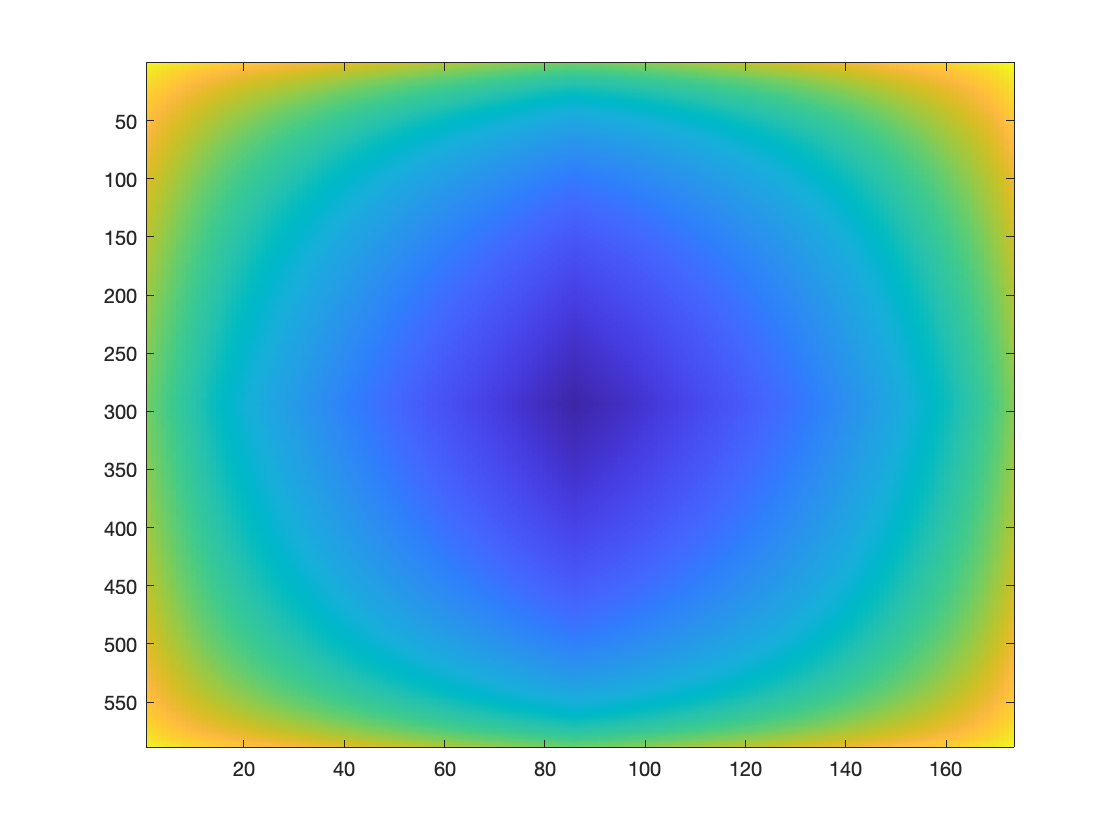

imagesc(N_co_geoid)

function H1 = addPadding(H)
    sizeH = size(H);
    H1 = [H,zeros([sizeH(1) sizeH(2)-1]);zeros([sizeH(1)-1 sizeH(2)]),zeros([sizeH(1)-1 sizeH(2)-1])];
  % H1 =  [zeroH,zeroH,zeroH;zeroH,H,zeroH;zeroH,zeroH,zeroH];
end
function H1 = addPadding_full(H)
    sizeH = size(H);
    zeroH = zeros(sizeH);
  %  H1 = [H,zeros([sizeH(1) sizeH(2)-1]);zeros([sizeH(1)-1 sizeH(2)]),zeros([sizeH(1)-1 sizeH(2)-1])];
     H1 =  [zeroH,zeroH,zeroH;zeroH,H,zeroH;zeroH,zeroH,zeroH];
end


%------------------------------------------------------
function gammas = gammas(latitude)
    a = 6378137.0;
    b = 6356752.314140;
    gamma_a = 9.7803267714;
    gamma_b = 9.8321863685;
    omega = 7292115.0*10^11;
    GM = 3986004.418*10^8 ;
    m = ((omega^2)*(a^2)*b)/GM;
    f = (a-b)/a;
    gammas = (a*gamma_a*(cosd(latitude).^2) + b*gamma_b*(sind(latitude).^2))./((a*(cosd(latitude).^2)+b*(sind(latitude).^2)).^0.5);
end